# **Compatibility Considerations**

## Web graphics support.

In R2016a, MathWorks introduced JavaScript-based MATLAB graphics (*web graphics*) alongside the earlier Java-based system. Web graphics offers additional components and deployment technologies, and has been maturing ever since. The web graphics system is accessed by creating a figure using the [`uifigure`](https://www.mathworks.com/help/matlab/ref/uifigure.html) function rather than the [`figure`](https://www.mathworks.com/help/matlab/ref/figure.html) function.

Many developers using GUI Layout Toolbox have requested web graphics support. This actually depends mostly on feature completeness of the web graphics system itself, rather than changes to GUI Layout Toolbox.

From R2020b, GUI Layout Toolbox has partially supported web graphics. From R2022b, all types are supported, with improvements to come.

### Support

- Simple box, grid, and card layouts are supported from R2020b.

- Flexible box and grid layouts are supported from R2022a, as are scrolling and tab layouts.

- Box panels are supported from R2022a.

In detail:

### Usage

To use GUI Layout Toolbox in web graphics, the `AutoResizeChildren` property of any ancestor [`uifigure`](https://www.mathworks.com/help/matlab/ref/uifigure.html), [`uipanel`](https://www.mathworks.com/help/matlab/ref/uipanel.html), or [`uitab`](https://www.mathworks.com/help/matlab/ref/uitab.html) must be set to `'off'`, otherwise the layouts will not resize as expected.

For example, to create a flexible grid in a `uifigure`:

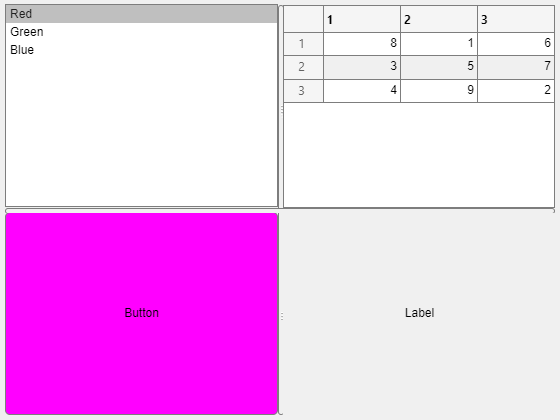

f = uifigure( "AutoResizeChildren", "off" );
g = uix.GridFlex( "Parent", f, "Padding", 5 );
uilistbox( g, "Items", ["Red", "Green", "Blue"] );
uibutton( g, "Text", "Button", "BackgroundColor", "m" );
uitable( g, "Data", magic(3) );
uilabel( g, "Text", "Label", "HorizontalAlignment", "center" );
g.Widths = [-1, -1];

To create a card panel in a `uipanel`:

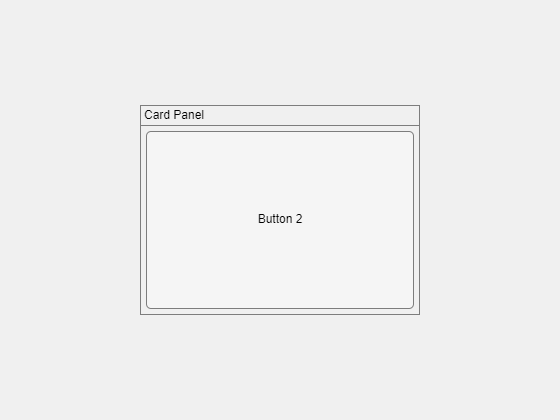

f = uifigure( "AutoResizeChildren", "off" );
p = uipanel( "Parent", f, ...
    "Title", "Card Panel", ...
    "Units", "normalized", ...
    "Position", [0.25, 0.25, 0.50, 0.50], ...
    "AutoResizeChildren", "off" );
cp = uix.CardPanel( "Parent", p, "Padding", 5 );
uibutton( cp, "Text", "Button 1" );
uibutton( cp, "Text", "Button 2" );

## **Minimum MATLAB version**

This is version 2 of GUI Layout Toolbox, designed to work with the new MATLAB graphics system that was introduced in R2014b. Version 1 works with MATLAB releases prior to R2014b that use the old graphics system.

## Compatibility with version 1

If you are upgrading from version 1, there are a number of compatibility considerations.

### Namespace name

Version 1 classes were contained in the namespace `uiextras`. Version 2 classes are contained in the namespace `uix`. In version 2, a namespace `uiextras` is included to provide support for legacy code. Classes in `uiextras` extend the corresponding classes in `uix`, and contain only compatibility-related code.

### `Contents` property

The contents of version 1 objects were accessible via the property `Children`. The contents of version 2 objects are accessible via the property `Contents`. Version 2 objects also provide a property `Children`, but this controls the vertical stacking order rather than the layout order. Legacy code that accesses `Children` will run without error, but will not achieve the desired change in layout order, and should be modified to access `Contents` instead.

An upcoming release of version 1 will include support for code that references contents via `Contents`. That way, code modified to work in version 2 will also work in version 1.

The background to this change is as follows. Version 1 classes were wrappers for built-in graphics classes, and presented contents in layout order via the property `Children`. Version 2 objects extend built-in graphics objects, and as such, inherit properties, methods, and events. One such property is `Children`, which is used to control the top-to-bottom stacking order. MATLAB stacking rules, e.g., controls are always on top of axes, mean that some reasonable layout orders may be invalid stacking orders, so a new property for layout order is required.

Another difference between `Children` and `Contents` relates to the `HandleVisibility` of the graphics objects placed in a layout. The `Children` property does not include graphics objects with `HandleVisibility` set to `'off'`. However, the `Contents` property includes all graphics objects placed in the layout, including those with `HandleVisibility` set to `'off'`. This difference ensures that users are able to specify the layout of all child elements placed in a layout.

### Autoparenting

The new MATLAB graphics system introduces unparented objects, i.e., those with property `Parent` empty. The new system also introduces a separation between formal class constructors, e.g., `matlab.ui.container.Panel`, and informal construction functions, e.g., `uipanel`. Construction functions are autoparenting, i.e., if `Parent` is not specified then it is set to [`gcf`](https://www.mathworks.com/help/matlab/ref/gcf.html), whereas class constructors return objects with `Parent` empty unless explicitly specified. Version 2 presents a formal interface of class constructors which follow this new convention.

Classes in `uiextras` are autoparenting, so the behavior of legacy code is unchanged. However, best practice is to specify the parent explicitly during construction.

### Defaults mechanism

Version 1 provided a defaults mechanism (`uiextras.get`, `uiextras.set`, and `uiextras.unset`) that mimicked [`get`](https://www.mathworks.com/help/matlab/ref/get.html) and [`set`](https://www.mathworks.com/help/matlab/ref/set.html) in the MATLAB graphics system. This feature has been removed from version 2. Users should use an alternative programming pattern, e.g., a factory function, to create objects with standard settings.

### Enable and disable

Version 1 provided a mechanism to enable and disable container contents using the property `Enable`. This feature has been removed from version 2. Users should enable and disable controls directly rather than via containers. For more commentary, see [this article](https://stackoverflow.com/questions/305527/how-to-disable-a-container-and-its-children-in-swing).

### Other property name changes

A number of property names have changed to achieve greater consistency across the namespace. For example, `RowSizes` and `ColumnSizes` in `uiextras.Grid` are now `Heights` and `Widths` in `uix.Grid`. The namespace `uiextras` provides support for legacy property names.

### Property shape changes

Version 2 contents companion properties are now of the same size as `Contents`, i.e., column vectors. In version 1, these properties were row vectors. The namespace `uiextras` provides support for legacy property values.

### Tab selection behavior

In version 1, after adding a tab to a tab panel, the new tab is selected.

In version 2, the original selection is preserved, except if the tab panel was empty, in which case the new tab is selected. This is consistent with the behavior of [`uitabgroup`](https://www.mathworks.com/help/matlab/ref/uitabgroup.html).